clear;
raw_data = readmatrix('./output/4_CORNERS_WAR_SIMULATION_05_32_25_06_03_2025.txt')

raw_data = 1.0e+05 *

         0         0         0         0         0         0         0         0         0         0         0
    0.0019    2.3040    0.5274    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0019    2.3040    0.5274    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0019    2.3039    0.5274    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0019    2.3039    0.5274    0.0000    0.0000    0.0000    0.0000    0.0001    0.0000    0.0000    0.0000
    0.0019    2.3039    0.5274    0.0000    0.0000    0.0000    0.0000    0.0001    0.0000    0.0000    0.0000
    0.0019    2.3038    0.5274    0.0000    0.0000    0.0000    0.0000    0.0001    0.0000    0.0000    0.0000
    0.0019    2.3038    0.5274    0.0001    0.0000    0.0000    0.0000    0.0001    0.0000    0.0000    0.0000
    0.0020    2.3037    0.5273    0.0001    0.0000    0.0000    0.0000    0.0002    0.0000


p = (size(raw_data, 2) - 1)/2 - 1

p = 4

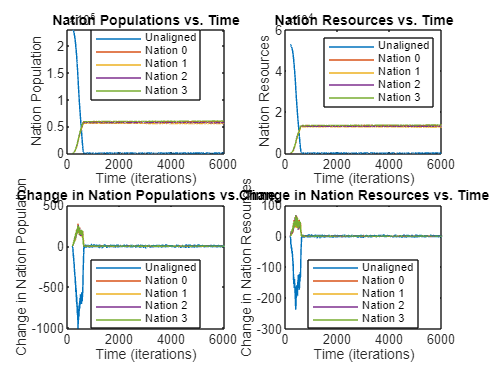

t = raw_data(2:end, 1);
nation_pops = zeros(length(t), p + 1);
nation_resources = zeros(size(nation_pops));

labels = cell(p + 1, 1);

for i = 1:(p+1)
    nation_pops(:, i) = raw_data(2:end, 2*i);
    nation_resources(:, i) = raw_data(2:end, 1 + 2*i);

    if (i == 1) 
        labels{i} = "Unaligned";
    else
        labels{i} = ['Nation ', num2str(i - 2)];
    end
end

figure;
subplot(2, 2, 1);
for i = 1:(p + 1)
    plot(t, nation_pops(:, i));
    hold on;
end
title("Nation Populations vs. Time");
xlabel("Time (iterations)");
ylabel("Nation Population");
legend(labels, 'location', 'best');

subplot(2, 2, 2);
for i = 1:(p + 1)
    plot(t, nation_resources(:, i));
    hold on;
end
title("Nation Resources vs. Time");
xlabel("Time (iterations)");
ylabel("Nation Resources");
legend(labels);

subplot(2, 2, 3);
for i = 1:(p + 1)
    plot(t(2:end), diff(nation_pops(:, i), 1, 1));
    hold on;
end
title("Change in Nation Populations vs. Time");
xlabel("Time (iterations)");
ylabel("Change in Nation Population");
legend(labels, 'location', 'best');

subplot(2, 2, 4);
for i = 1:(p + 1)
    plot(t(2:end), diff(nation_resources(:, i), 1, 1));
    hold on;
end
title("Change in Nation Resources vs. Time");
xlabel("Time (iterations)");
ylabel("Change in Nation Resources");
legend(labels, 'location', 'best');